# Walsh-Hadamard Transform of a Signal

This example shows a simple input signal and its Walsh-Hadamard transform.

x = [19 -1 11 -9 -7 13 -15 5];
y = fwht(x)

y =      2     3     0     4     0     0    10     0


`y` contains nonzero values at locations 0, 1, 3, and 6. Form the Walsh functions with the sequency values 0, 1, 3, and 6 to recreate x.

w0 = [1 1 1 1 1 1 1 1];
w1 = [1 1 1 1 -1 -1 -1 -1];
w3 = [1 1 -1 -1 1 1 -1 -1];
w6 = [1 -1 1 -1 -1 1 -1 1];
w = y(0+1)*w0 + y(1+1)*w1 + y(3+1)*w3 + y(6+1)*w6

w =     19    -1    11    -9    -7    13   -15     5


Obtain the same result by extracting the nonzero values and Walsh functions programmatically.

ww = fwht(eye(length(y)))*length(y)

ww =      1     1     1     1     1     1     1     1
     1     1     1     1    -1    -1    -1    -1
     1     1    -1    -1    -1    -1     1     1
     1     1    -1    -1     1     1    -1    -1
     1    -1    -1     1     1    -1    -1     1
     1    -1    -1     1    -1     1     1    -1
     1    -1     1    -1    -1     1    -1     1
     1    -1     1    -1     1    -1     1    -1


nz = find(y);
w = sum(y(nz)'.*ww(nz,:))

w =     19    -1    11    -9    -7    13   -15     5


n=8

n = 8

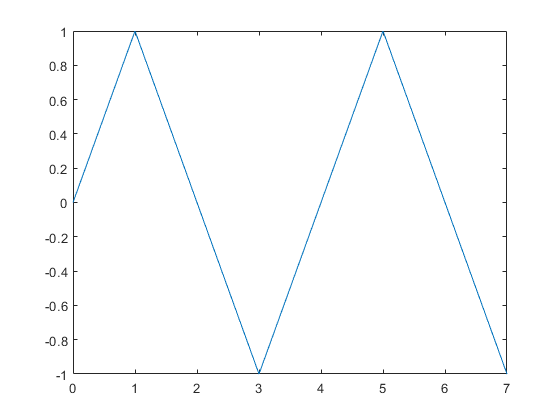

t=linspace(0, n-1, n);
w0=2*pi*2;
sig = sin(w0/n*t);
plot(t, sig)

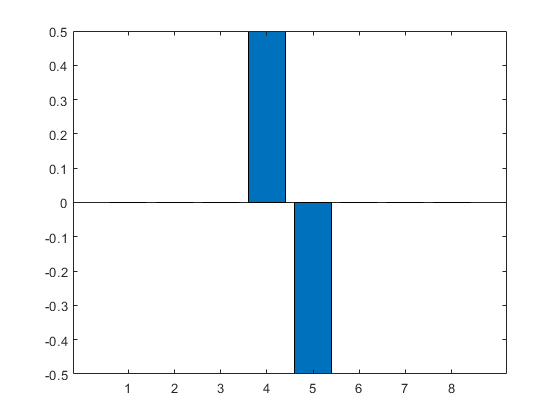

y = fwht(sig);
y0 = abs(y);
bar(y)

yy=sqrt(pow2(y(4))+pow2(y(5)))

yy = 1.4565

n=16

n = 16

H = hadamard(n)

H =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1
     1     1    -1    -1     1     1    -1    -1     1     1    -1    -1     1     1    -1    -1
     1    -1    -1     1     1    -1    -1     1     1    -1    -1     1     1    -1    -1     1
     1     1     1     1    -1    -1    -1    -1     1     1     1     1    -1    -1    -1    -1
     1    -1     1    -1    -1     1    -1     1     1    -1     1    -1    -1     1    -1     1
     1     1    -1    -1    -1    -1     1     1     1     1    -1    -1    -1    -1     1     1
     1    -1    -1     1    -1     1     1    -1     1    -1    -1     1    -1     1     1    -1
     1     1     1     1     1     1     1     1    -1    -1    -1    -1    -1    -1    -1    -1
     1    -1     1    -1     1    -1     1    -1    -1     1    -1     1    -1     1    -1     1
